定义增益矩阵k3，将反馈力以正确的维数反馈到数值子结构

13：第三层横向位移

21：物理子结构转角

26：第二层横向位移

27：第一层横向位移

29：物理子结构另一个转角（此转角不受控）

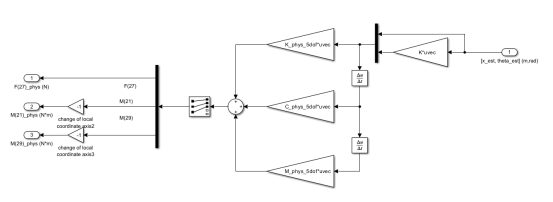

k3 = zeros(5,5);
k3(4,1) = 1;
k3(2,2) = -1;
k3(5,3) = -1;

M5 = M_phys_5dof;
C5 = C_phys_5dof;
K5 = K_phys_5dof;

Gps_tf = k3*(M5*s^2+C5*s+K5);
Gpd_tf = c2d(Gps_tf,dt,'tustin');
Gps_ss = ss(Gps_tf);
Gpd_ss = c2d(Gps_ss,dt,'tustin');

bode图

%bode(Gp_ss,Gp_tf)

单位激励下的响应